dt = 0.1;
time = 0:dt:50;

%System parameters
a = 0.1;
b = 0.5;
T_env = 25;
T = 25;

%PID gains
Kp = 2.0;
Ki = 0.1;
Kd = 1.0;

setpoint = 60;

%Storage
temps = zeros(size(time));
control = zeros(size(time));

%PID variables
integral = 0;
prev_error = setpoint - T;

for i = 1:length(time)
    error = setpoint - T;
    integral = integral + error * dt;
    derivative = (error - prev_error) / dt;

    u = Kp*error + Ki*integral + Kd*derivative;

   temps(i) = T;

    %System dynamics
    dTdt = -a*(T - T_env) + b*u;
    T = T + dTdt * dt;
    
    control(i) = u;

    prev_error = error;
end
disp(T)

   59.9128



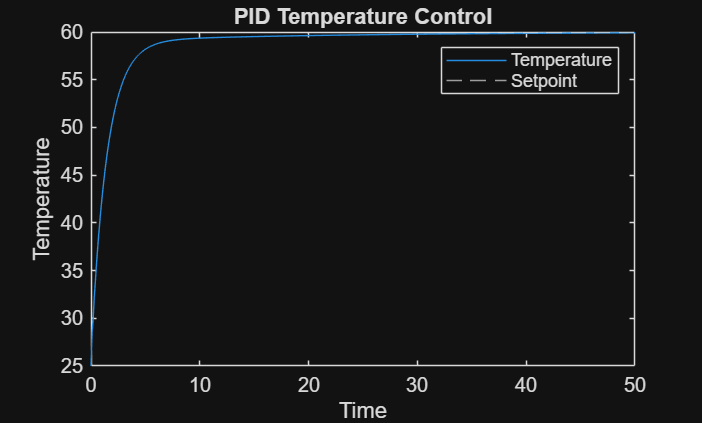


plot(time,temps)
hold on
yline(setpoint, '--')
xlabel('Time')
ylabel('Temperature')
title('PID Temperature Control')
legend('Temperature','Setpoint')